# The celestial.map.plot_monthly_smap function

# in the astronomy & astrophysics toolbox for MATLAB

## Description:

A function to plot a sky map showing the bright stars abobe the local horizon. This file is accessible through the `manual` package (i.e. `manual.plot_monthly_smap`). The `celestial.map.plot_monthly_smap` function is part of the [celestial package](https://webhome.weizmann.ac.il/home/eofek/matlab/doc/celestial.html).

## Credit

If you are using this code or products in your scientific publication please give a reference to [Ofek (2014; ascl.soft 07005)](http://adsabs.harvard.edu/abs/2014ascl.soft07005O).

## License

Unless specified otherwise this code and products are released under the GNU general public license version 3.

## Installation

See[ http://weizmann.ac.il/home/eofek/matlab/doc/install.html ](http://webhome.weizmann.ac.il/home/eofek/matlab/doc/install.html)for installation instruction and additional documentation.

# Examples

Plot the current skymap with default geodetic position (Israel):

celestial.map.plot_monthly_smap(celestial.time.julday)

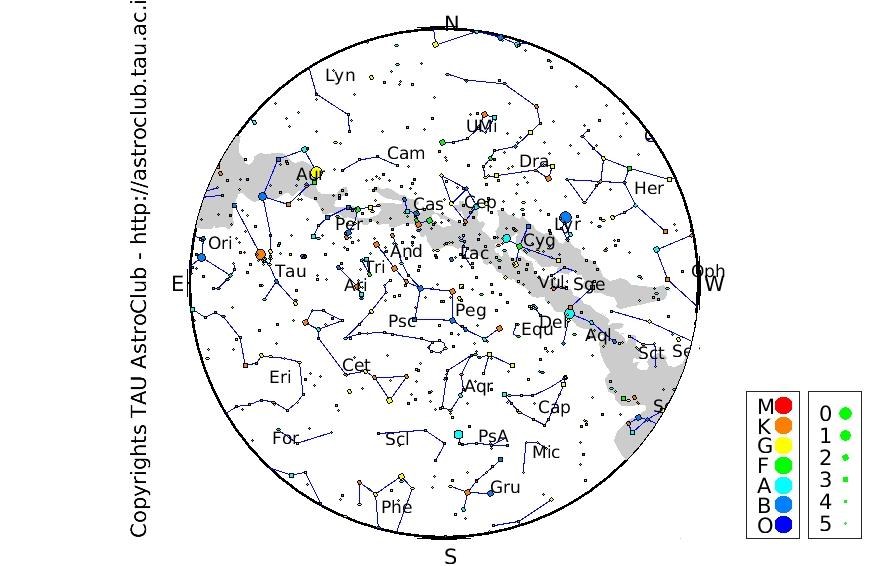

To view the full options and help:

help celestial.map.plot_monthly_smap

  Plot a monthly sky map
  Package: celestial.map
  Description: Plot a monthly sky map with a naked eye stars for a given
               time and observer Geodetic position. Optionaly mark planets
               position, constellations and the milky way.
  Input  : - Date [D M Y H M S]  | 
             Date [D M Y Frac] |
             JD.
           * arbitrary number of keyword and properties, where keywods are:
             'GeodPos'    - Geodetic poistion
                            [East Long, North Lat, Height(m)] 
                            in radians, default is [35 32 0]./RAD.
             'Cat'        - Star Catalog, default is mag6.mat 
             'ColRA'      - RA column in star catalog, default is 1.
             'ColDec'     - RA column in star catalog, default is 2.
             'ColMag'     - Mag column in star catalog, default is 3.
             'ColCol'     - Color (B-V) column in star catalog,
                            default is 4.
             'ColPMRA'    - 

The function allows for keyword,value input pairs. For example, plot a star map for 2019-Jan-01 at 22:00:00 (UTC) forsome location on Earth and include all planets:

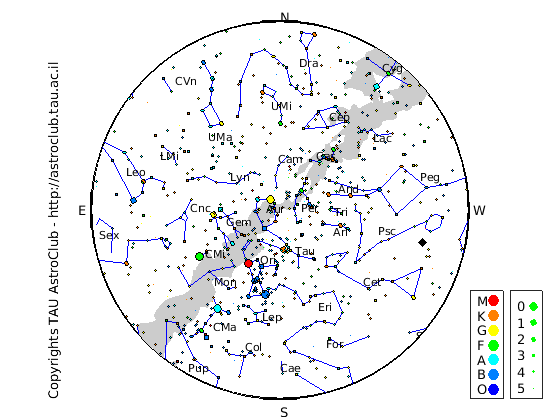

celestial.map.plot_monthly_smap([1 1 2019 22 00 00],'GeodPos',[0,40,0].*pi./180,'Planets','All')

The function has a large number of options, controling all aspects of its apperance. Furthermore, proper motion and precession are included (see help).